# **Exploring Risk Contagion Using Graph Theory and Markov Chains**

Recent financial crises and periods of market volatility have heightened awareness of risk contagion and systemic risk among financial analysts. As a result, financial professionals are often tasked with constructing and analyzing models that will yield insight into the potential impact of risk on investments, portfolios, and business operations.

Several authors have described the use of advanced mathematical and statistical techniques for quantifying the dependent relationships between investments, foreign exchange rates, industrial sectors, or geographical regions [1]-[7]. Bridging the gap between formal methods and a working code implementation is a key challenge for analysts.

This example shows how MATLAB can be used to analyze aspects of risk contagion using various mathematical tools. Topics covered include:

- Data aggregation, preprocessing, and risk benchmarking

- Quantifying dependent relationships between financial variables

- Visualizing the resulting network of dependencies together with proximity information

- Analyzing periods of risk contagion using hidden Markov models

The MATLAB code used in this article is available for [download](https://mathworks.com/matlabcentral/fileexchange/57046-exploring-risk-contagion-using-graph-theory-and-markov-chains-live-editor-version).

*Copyright 2016-2023 The MathWorks, Inc.*

## **Data aggregation and preprocessing.**

We start with a collection of mid-cap security prices from various countries recorded over the period January 2008–December 2013. Each security comes with associated metadata such as market capitalization, industrial sector, and country. In this article we will be analysing the contagion between different sectors, but it is easy to study alternative groupings – for example, country of origin. We use the normalized market capitalizations to define individual security weights and then aggregate all securities from each sector using a weighted sum. The result is the benchmark price series defined below.

### Load the data.

load("MidCapData.mat")

### Construct sector benchmarks.

Each sector benchmark is the weighted sum of the prices of the stocks within that sector. The weights are defined using the relative market capitalizations of each stock.

marketCapWeights = meta.MarketCap / sum(meta.MarketCap);
sectors = categories(meta.Sector);
prices = midcap.Variables;
for k = numel(sectors):-1:1
    % Logical index for the current sector.
    sectorIdx = meta.Sector == sectors{k};
    % Compute each sector benchmark using a weighted sum.
    sectorBenchmarks(:, k) = ...
        prices(:, sectorIdx) * marketCapWeights(sectorIdx);
end % for

### Visualize the sector benchmarks.

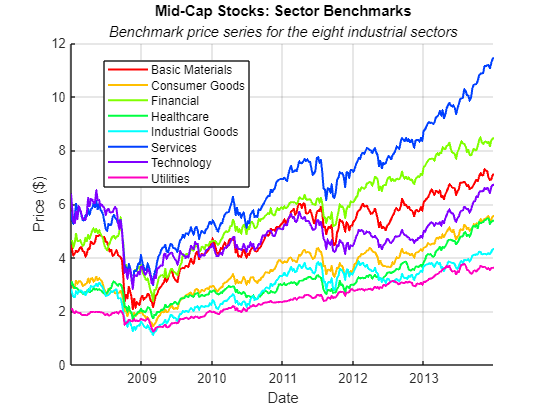

figure
hold on
numSectors = numel(sectors);
plotColors = hsv(numSectors);
for k = 1:numSectors
    plot(midcap.Dates, sectorBenchmarks(:, k), ...
        "Color", plotColors(k, :), "LineWidth", 1.5)
end % for
xlabel("Date")
ylabel("Price ($)")
title("Mid-Cap Stocks: Sector Benchmarks")
subtitle("Benchmark price series for the eight industrial sectors", "FontAngle", "italic")
grid on
legend(sectors, "Location", "best")

### Compute the sector benchmark returns and visualize the resulting series.

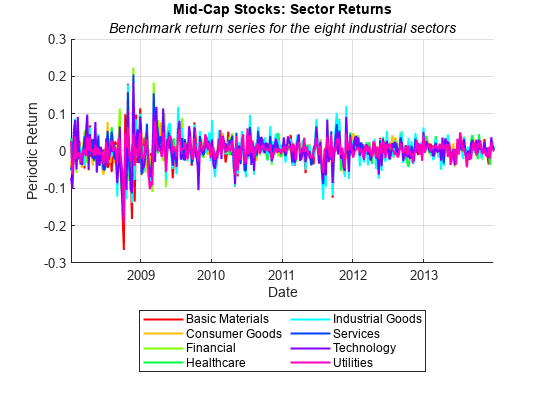

sectorRets = tick2ret(sectorBenchmarks);
figure
hold on
for k = 1:size(sectorRets, 2)
    plot(midcap.Dates(2:end), sectorRets(:, k), ...
        "Color", plotColors(k, :), "LineWidth", 1.5)
end % for
xlabel("Date")
ylabel("Periodic Return")
title("Mid-Cap Stocks: Sector Returns")
subtitle("Benchmark return series for the eight industrial sectors", "FontAngle", "italic")
grid on
legend(sectors, "Location", "southoutside", "NumColumns", 2)

## Correlation analysis.

One of the simplest ways to study dependencies between variables is to compute the correlation matrix of the data. Using the MATLAB [`plotmatrix`](matlab: doc plotmatrix) function and the Statistics and Machine Learning Toolbox™ [`corr`](matlab: doc corr) function, we can create informative visualizations that indicate the pairwise relationships present in the sector return series data. Examples of these charts are shown below.

The off-diagonal elements in the plot matrix show the pairwise joint distributions, and the diagonal shows the marginal distributions of each variable on a histogram. The correlation coefficients between the industrial sector returns quantify the relative strength of the pairwise linear relationships shown in the plot matrix. 

To investigate more general monotonic relationships between variables, we could compute Kendall’s $\tau$ or Spearman’s $\rho$ coefficient using the `corr` function.

### Compute dependencies between variables.

One basic approach for this is to compute the pairwise correlation between the different sectors' return series. First, we visualize the pairwise joint distributions using the `plotmatrix` function. This provides some insight into the pairwise relationships between the variables, as well as the shape of the marginal variable distributions.

figure
[~, ax, bigAx] = plotmatrix(sectorRets, "b.");
title(bigAx, "Pairwise Sector Return Distributions")

Remove axis tick labels.

set(ax, "XTickLabel", "", "YTickLabel", "")

Annotate the chart with the sector names.

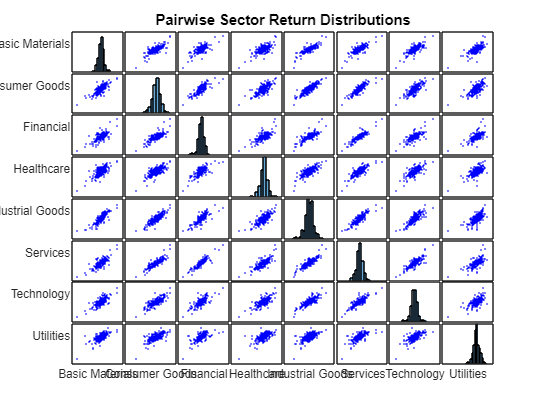

for k = 1:numel(sectors)
    ylabel(ax(k, 1), sectors{k}, "Rotation", 0, ...
        "HorizontalAlignment", "right")
    xlabel(ax(end, k), sectors{k})
end % for

This chart shows the empirical pairwise relationships between the sector returns.

### Next, compute and visualize the pairwise correlation coefficients.

This chart is a [`heatmap`](matlab: doc heatmap) showing the pairwise sector linear correlation coefficients, highlighting all correlations above a certain threshold value (0.80).

sectorCorr = corr(sectorRets);

Define a custom colormap.

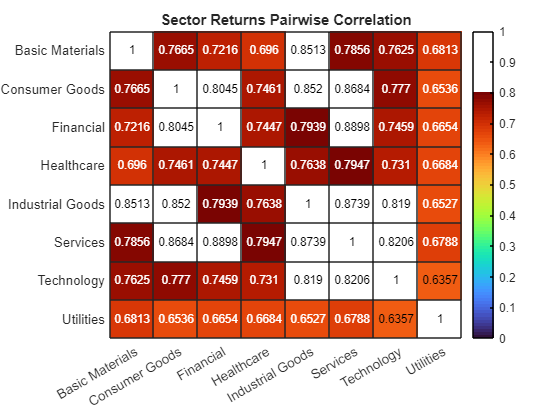

white = [1, 1, 1];
cmap = [turbo(80); repmat(white, 20, 1)];

figure
heatmap(sectors, sectors, sectorCorr, ...
    "ColorLimits", [0, 1], ...
    "Colormap", cmap)
title("Sector Returns Pairwise Correlation")

## Visualizing dependencies using graph theory.

It can be difficult to gain insight into risk contagion directly from a correlation matrix. Applying graph theory is an effective technique for quantifying and visualizing the proximity of variables. To measure proximity, we convert correlation coefficients $C$ into distances using a mapping such as$$f(C) = 1 - C $$or $$f(C) = \sqrt{2(1-C)}$$.

### Convert correlation coefficients to distances.

Correlation coefficients $C$ do not provide a valid distance metric, because they can be negative. However, it is straightforward to transform them into distances, for example by setting $D = 1-C$ (as used by the [`pdist`](matlab: doc pdist) function with its `"correlation"` parameter). Another commonly used metric is $D=\sqrt{2(1-C)}$.

sectorDist = sqrt(2*(1-sectorCorr));

Create a heatmap showing the pairwise correlation distances between the different sectors. Note that as the correlation coefficients have a range of $[-1, 1]$, the distance $D$ has a possible range of $[0, 2]$.

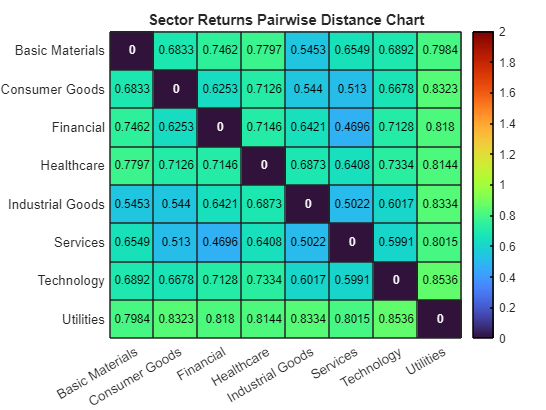

figure
heatmap(sectors, sectors, sectorDist, ...
    "ColorLimits", [0, 2], ...
    "Colormap", turbo())
title("Sector Returns Pairwise Distance Chart")

### Translate the distance information into graph form.

Assigning the industrial sectors to the nodes of a network, we then join up the nodes via edges with lengths given by the correlation distance. In [1] and [2], the authors compute the *minimum spanning tree* (MST) of this graph. The MST is a subgraph connecting all nodes in which the total edge length is minimized. In this context, we can think of the MST as the “backbone” network encapsulating the dependencies between sectors. In MATLAB we can use the [`graph`](matlab: doc graph) and [`minspantree`](matlab: doc minspantree) functions to compute the MST directly.

First, we remove small numerical asymmetries (since the `graph` function requires a perfectly symmetric adjacency matrix). 

Here, `sectorDist` is the correlation distance matrix and `sectors` contains the sector names.

sectorDist = (sectorDist + sectorDist.')/2;
G = graph(sectorDist, sectors);

Compute the minimal spanning tree.

T = minspantree(G);

There are several options for visualizing the resulting MST. The simplest approach is to use the graph `plot` function directly on the tree. An alternative approach providing a 2D representation [1] is to use nonlinear multi-dimensional scaling on the distance matrix via the Sammon mapping. To create a 2D visualization, we pass the resulting array of Euclidean coordinates `coords` to the `graph` class `plot` method. When combined with some simple plot settings, this approach allows us to create the visualization below.

Embed the distance matrix in Euclidean space using the Sammon mapping.

[coords, stress, disparities] = mdscale(sectorDist, 3, ...
    "Criterion", "Sammon", ...
    "Replicates", 20);
edgeWeights = T.Edges.Weight;
edgeWidths = 3*edgeWeights/max(edgeWeights);

Visualize the minimum spanning tree created using the correlation distance metric.

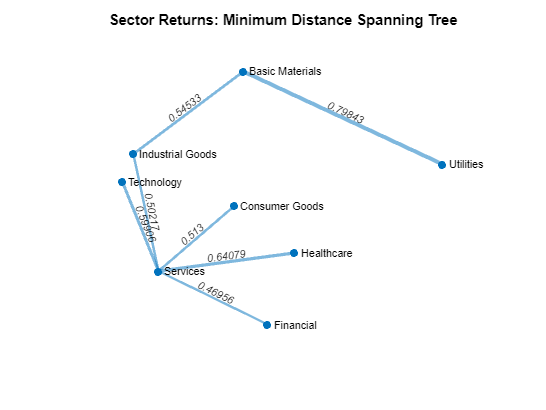

figure
treePlot = plot(T, "XData", coords(:, 1), ...
    "YData", coords(:, 2), ...
    "EdgeLabel", edgeWeights, ...
    "LineWidth", edgeWidths, ...
    "MarkerSize", 5);
title("Sector Returns: Minimum Distance Spanning Tree")    
axis off

### Assess the quality of the embedding.

We assess the quality of the graph embedding by creating a Shepard plot. If the scattered points do not deviate substantially from the reference line, then we have a good quality embedding.

Concatenate the disparities and the sector distances into one matrix for sorting.

D = [disparities(:), sectorDist(:)];
mdscaleDist = squareform(pdist(coords));
[~, sortPos] = sortrows(D, 1);

Create the Shepard plot of Sammon embedding distance against the actual distance.

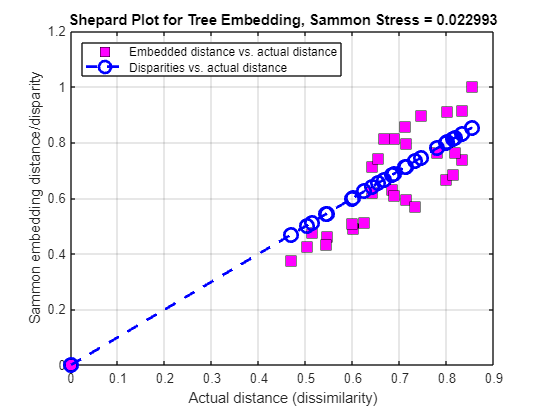

figure
plot(sectorDist(:), mdscaleDist(:), "ks", "MarkerSize", 10, "MarkerFaceColor", "m")
hold on
plot(sectorDist(sortPos), disparities(sortPos), "bo--", "MarkerSize", 10, "LineWidth", 2)
ylabel("Sammon embedding distance/disparity")
xlabel("Actual distance (dissimilarity)")
title("Shepard Plot for Tree Embedding, Sammon Stress = " + num2str(stress, "%.6f"))
grid on
legend("Embedded distance vs. actual distance", ...
    "Disparities vs. actual distance", ...
    "Location", "northwest")

## Assessing sector importance using graph centrality measures.

Representing the data in graph form helps us to quantify relationships between variables. Since mathematical graphs intrinsically provide measures of node significance, we can assess sector importance by computing these quantities. We use the [`centrality`](matlab: doc centrality) method associated with `graph` objects.

### Compute various centrality metrics derived from the sector tree.

incidence = centrality(T, "degree");
closeness = centrality(T, "closeness", "Cost", edgeWeights);
betweenness = centrality(T, "betweenness", "Cost", edgeWeights);

The *incidence* of a node counts the number of edges adjoining that node, whereas the *closeness* is the reciprocal of the sum of the distances from the node to all other nodes. A high closeness value therefore implies that the node is central, or important. 

Similarly, the *betweenness* of a node measures how often that node appears on a shortest path between two other nodes in the graph. A high betweenness value implies that the node is important. 

Computing these measures for the MST above produces the results shown below. We see that the services sector has the highest values for all measures. The central services node is highlighted in red.

Begin with the node incidence.

figure
tiledlayout(2, 2)
nexttile([2, 1])
[incSort, sortPos] = sort(incidence);
barh(1:2:numel(incSort), incSort(1:2:end), "FaceColor", "b", "BarWidth", 0.25, "FaceAlpha", 0.5)
hold on
barh(2:2:numel(incSort), incSort(2:2:end), "FaceColor", "r", "BarWidth", 0.25, "FaceAlpha", 0.5)
xticks(0:max(incSort))
nodeNames = T.Nodes.Name(sortPos);
yticks(1:numel(nodeNames))
yticklabels(nodeNames)
grid on
xlabel("Node Incidence")
title("Sector Returns Tree Node Incidence")

Visualize closeness and betweenness.

nexttile(2)
[closeSort, sortPos] = sort(closeness, "descend");
stem(closeSort, "LineWidth", 2, "MarkerSize", 8)
xlim([0, numel(closeSort)+1])
xticks(1:numel(closeSort))
nodeNames = T.Nodes.Name;

Truncate the sector names for compactness.

truncNodeNames = cellfun(@(W) W(1:3), nodeNames, "UniformOutput", false);
xticklabels(truncNodeNames(sortPos))
ylabel("Closeness")
title("Sector Returns Tree Node Closeness")
grid on

Visualize the sector centrality measures computed from the MST.

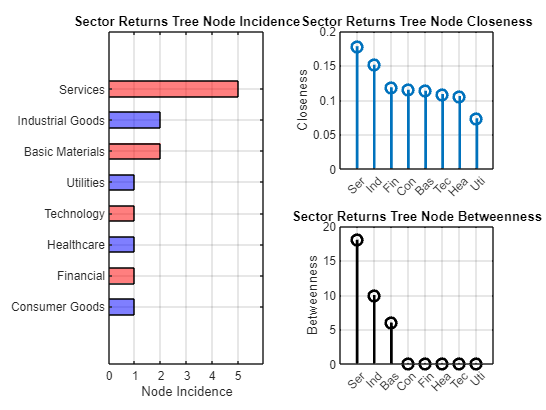

nexttile(4)
[betSort, sortPos] = sort(betweenness, "descend");
stem(betSort, "LineWidth", 2, "MarkerSize", 8, "Color", "k")
xlim([0, numel(betSort)+1])
xticks(1:numel(betSort))
xticklabels(truncNodeNames(sortPos))
ylabel("Betweenness")
title("Sector Returns Tree Node Betweenness")
grid on

### Highlight the most central node on the tree by changing the color.

[~, centralNodeIdx] = max(closeness);
nodeColor = treePlot.NodeColor;
nodeColors = repmat(nodeColor, numel(T.Nodes), 1);
nodeColors(centralNodeIdx, :) = [1, 0, 0];
treePlot.NodeColor = nodeColors;

Increase the marker size of the central node. This chart shows the correlation distance dependency network for industrial sector returns, with the central sector highlighted in red.

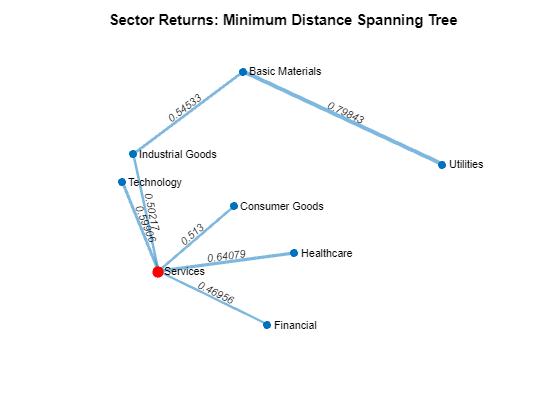

nodeMarkerSize = treePlot.MarkerSize;
nodeMarkerSizes = repmat(nodeMarkerSize, numel(T.Nodes), 1);
nodeMarkerSizes(centralNodeIdx) = 1.5*nodeMarkerSize;
treePlot.MarkerSize = nodeMarkerSizes;

## Visualizing risk contagion via rolling windows.

The analysis described in the previous section uses the full data set from 2008–2013. It is common in risk models to perform analysis in a rolling window so as to assess dynamic changes in variables of interest. To implement the previous analysis in sequential six-month rolling windows, we use a `for`-loop to increment the start date for each window. This will provide insight into how the risk associations vary with time.

The graphics from this process can be captured in a video file using the [`VideoWriter`](matlab: doc VideoWriter) class, showing the incidence of highly correlated (> 0.80) sector pairs over time.

Start with the calculations for the initial frame.

We use a 6-month rolling window (26 weeks).

windowSize = 26; 
windowedSectorCorr = corr(sectorRets(1:windowSize, :));
windowedSectorDist = sqrt(2*(1-windowedSectorCorr));
windowedSectorDist = (windowedSectorDist + windowedSectorDist.')/2;
windowedFullGraph = graph(windowedSectorDist, sectors);
windowedMSTree = minspantree(windowedFullGraph);
windowedCoords = mdscale(windowedSectorDist, 3, "Criterion", "Sammon");
edgeWeights = windowedMSTree.Edges.Weight;
edgeWidths = 3*edgeWeights/max(edgeWeights);
dates = midcap.Dates;
windowedDates = dates(1:windowSize);

Graphics for the initial frame.

riskFig = figure;
tiledlayout(1, 2)
nexttile()
windowedTreePlot = plot(windowedMSTree, ...
    "XData", windowedCoords(:, 1), ...
    "YData", windowedCoords(:, 2), ...
    "EdgeLabel", edgeWeights, ...
    "LineWidth", edgeWidths, ...
    "MarkerSize", 5);
axis off
title("Sector Returns Tree")
dateTitle = subtitle(string(windowedDates(1), "dd/MM/yyyy") + ...
    "-" + string(windowedDates(end), "dd/MM/yyyy"));

Create the correlation chart.

nexttile()
corrHeatmap = heatmap(sectors, sectors, windowedSectorCorr, ...
    "ColorLimits", [0, 1], ...
    "Colormap", cmap);
title("Sector Returns Correlation")

Determine the most central vertex.

windowedCloseness = centrality(windowedMSTree, "closeness", "Cost", edgeWeights);
[~, centralNodeIdx] = max(windowedCloseness);
nodeColors = repmat(nodeColor, numel(sectors), 1);
nodeColors(centralNodeIdx, :) = [1, 0, 0];
windowedTreePlot.NodeColor = nodeColors;

Increase the marker size of the central node.

nodeMarkerSizes = repmat(nodeMarkerSize, numel(sectors), 1);
nodeMarkerSizes(centralNodeIdx) = 1.5*nodeMarkerSize;
windowedTreePlot.MarkerSize = nodeMarkerSizes;

This visualization shows the initial animation frame showing both the dependency network and heatmap.

### We also capture the output as a video stream.

This could be useful for subsequent offline analysis or for use in presentations.

vid = VideoWriter("RollingRiskContagion.avi");
vid.FrameRate = 2;
vid.Quality = 95;
open(vid)
writeVideo(vid, getframe(riskFig))

## Now update the data on a rolling basis.

Preallocate space for the central node indices (used later).

numFrames = height(sectorRets) - windowSize + 1;
centralSectorIdx = NaN(numFrames, 1);

Preallocate space for the number of highly correlated sector pairs.

nHighCorrPairs = NaN(numFrames, 1);

Update the data and graphics in a rolling window.

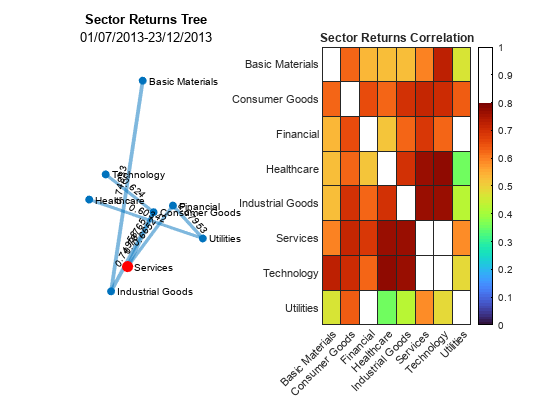

for k = 1:numFrames    
    
    % Update the data.
    windowedSectorCorr = corr(sectorRets(k:k+windowSize-1, :));
    windowedSectorDist = sqrt(2*(1-windowedSectorCorr));
    windowedSectorDist = (windowedSectorDist + windowedSectorDist.')/2;
    windowedFullGraph = graph(windowedSectorDist, sectors);
    windowedMSTree = minspantree(windowedFullGraph);
    windowedCoords = mdscale(windowedSectorDist, 3, "Criterion", "Sammon");
    edgeWeights = windowedMSTree.Edges.Weight;
    edgeWidths = 3*edgeWeights/max(edgeWeights);
    windowedDates = dates(k:k+windowSize-1);
    
    % Update the graphics.    
    set(windowedTreePlot, "XData", windowedCoords(:, 1), ...
        "YData", windowedCoords(:, 2), ...
        "EdgeLabel", edgeWeights, ...
        "LineWidth", edgeWidths)
    % Tree title.
    dateTitle.String = char(windowedDates(1), "dd/MM/yyyy") + ...
        "-" + char(windowedDates(end), "dd/MM/yyyy");    
    % Heatmap.
    corrHeatmap.ColorData = windowedSectorCorr;

    % Store the number of highly correlated sector pairs. Note that symmetry
    % means that pairs are counted twice.
    highCorrIdx = windowedSectorCorr - eye(numSectors) > 0.8;
    nHighCorrPairs(k) = nnz(highCorrIdx)/2;
    
    % Central node.
    windowedCloseness = centrality(windowedMSTree, "closeness", "Cost", edgeWeights);
    [~, centralSectorIdx(k)] = max(windowedCloseness);
    nodeColors = repmat(nodeColor, numel(sectors), 1);
    nodeColors(centralSectorIdx(k), :) = [1, 0, 0];
    windowedTreePlot.NodeColor = nodeColors;
    
    % Increase the marker size of the central node.
    nodeMarkerSizes = repmat(nodeMarkerSize, numel(sectors), 1);
    nodeMarkerSizes(centralSectorIdx(k)) = 1.5*nodeMarkerSize;
    windowedTreePlot.MarkerSize = nodeMarkerSizes;
    
    % Render each frame.
    drawnow()
    
    % Capture the updated frame.
    writeVideo(vid, getframe(riskFig))

end % for

### Finalize the video file.

close(vid)

## Track the central sector over time.

### Visualize the variation in the central sector over time.

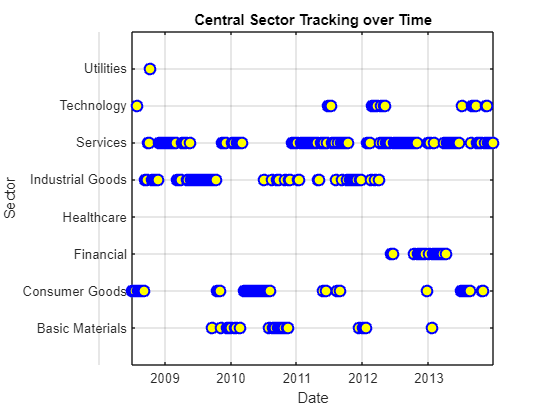

trackDates = dates(windowSize+1:end);

figure
plot(trackDates, centralSectorIdx, "bo", ...
    "MarkerSize", 8, ...
    "LineWidth", 1.5, ...
    "MarkerFaceColor", "y")
xlabel("Date")
ylabel("Sector")
title("Central Sector Tracking over Time")
grid on
yticks(1:numel(sectors))
yticklabels(sectors)
ylim([0, numSectors+1])

We note that the services, industrial goods, and consumer goods sectors have high importance throughout this period.

### Visualize the distribution of the central nodes over the rolling period.

Compute how many times each sector was the central node over time.

nodeCounts = accumarray(centralSectorIdx, ...
    ones(size(centralSectorIdx)), [numel(sectors), 1], @sum, 0);
[nodeCounts, sortPos] = sort(nodeCounts);

Visualize the counts and show the distribution of the central node over the rolling period.

figure
barh(1:2:numel(nodeCounts), nodeCounts(1:2:end), ...
    "FaceColor", "b", ...
    "FaceAlpha", 0.5, ...
    "BarWidth", 0.40, ...
    "LineWidth", 1)
hold on
barh(2:2:numel(nodeCounts), nodeCounts(2:2:end), ...
    "FaceColor", "r", ...
    "FaceAlpha", 0.5, ...
    "BarWidth", 0.40, ...
    "LineWidth", 1)
yticks(1:numel(nodeCounts))
yticklabels(sectors(sortPos))
title("Central Sector Distribution over the Rolling Period")
grid on

Add text labels for the counts.

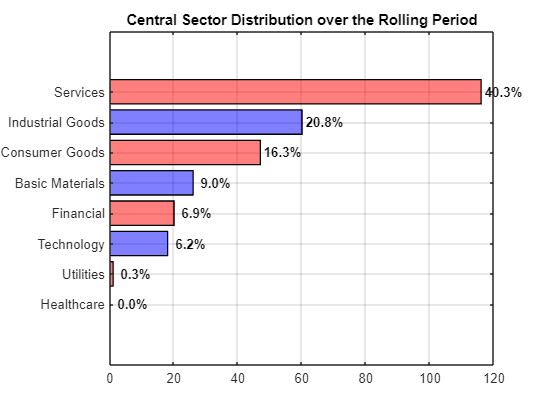

nodeCountsPC = 100*nodeCounts/sum(nodeCounts);
textLabels = " " + num2str(nodeCountsPC, "%.1f%%");
text(nodeCounts, 1:numel(nodeCounts), textLabels, ...
    "Color", "k", ...
    "FontWeight", "bold", ...
    "HorizontalAlignment", "left")

## Quantifying dependencies with alternative distance metrics.

Although correlation is simple to interpret and compute, it may not describe the complex nature of dependencies between financial variables completely. In [5], the author uses a metric based on the statistical concepts of entropy and mutual information theory. One advantage of using information content rather than correlation is that covariance matrices do not need to be computed. In fact, to compute information content, we just need a sequence of observed values so that we can estimate the joint density of the two variables under scrutiny. 

If $$f_X$$ is the probability density function of a random variable$$X$$, then the entropy of $$X$$ is


$$H_X = -\int_\mathbb{R} f_X(x)\log f_X(x)dx.$$


We can think of the entropy as a measure of the disorder, or randomness, of the variable. A high entropy indicates a high degree of disorder. Similarly, if we have two random variables$$X$$and $$Y$$with joint density $$f_{X,Y}$$, then the mutual entropy of$$X$$and$$Y$$is


$$H_{X, Y} = -\int_{\mathbb{R}^2} f_{X,Y}(x,y)\log f_{X,Y}(x, y)dxdy.$$


The *mutual information content* of$$X$$and $$Y$$is defined as


$$$$I_{X,Y} = H_X + H_Y - H_{X,Y}.$$$$


Mutual information can be converted into a distance using the formula


$$$$ d_{X,Y} = 1 - \sqrt{1-e^{-2I_{X,Y}}}.$$$$


Note that the maximum distance is one. This result is only achieved if the mutual information content of$$X$$and$$Y$$is zero, which, in turn, only occurs if$$X$$and$$Y$$are independent [5]. If$$X$$and$$Y$$are closely related, then their mutual information content is large, and consequently, the distance is close to zero.

We can estimate the joint density of two random variables in MATLAB using the Statistics and Machine Learning Toolbox function [`ksdensity`](matlab: doc ksdensity).  This technique has the advantage of avoiding any distributional assumptions on the data.

Assuming that$$X$$and$$Y$$are the return series for two sectors, sample code for computing $$H_{X,Y}$$ is as follows.

We take the first two sectors to illustrate the general process for computing information distance.

X = sectorRets(:, 1); % Basic materials
Y = sectorRets(:, 2); % Consumer goods

Compute and plot their joint kernel-smoothed density function. Make a grid for visualization purposes.

x = linspace(min(X), max(X), 250);
y = linspace(min(Y), max(Y), 250);
[Xgrid, Ygrid] = meshgrid(x, y);
pts = [Xgrid(:), Ygrid(:)];

Estimate the density values.

fXY = ksdensity([X, Y], pts);
fXY = reshape(fXY, size(Xgrid));

Compute the double integral.

integrandXY = fXY .* log(fXY);
integrandXY(isnan(integrandXY)) = 0;
HXY = - trapz(y, trapz(x, integrandXY, 2));

This code estimates the joint density of$$X$$and$$Y$$over a $$250\times250$$ lattice and then computes the double integral defining$$H_{X,Y}$$using the `trapz` function to perform numerical trapezoidal integration. Some `NaN` values occur in the integrand if the estimated values for $$f_{X,Y}$$ are zero. We will set these to zero before integrating. The chart shows the estimated joint density for the first two sectors, basic materials and consumer goods.

Visualize the density over this grid. This is the estimated joint density function for the first two industrial sectors.

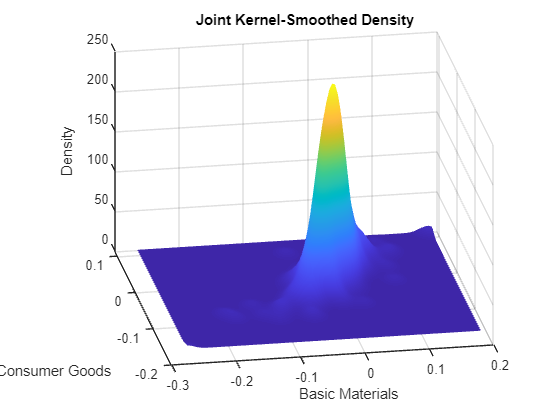

figure
ksdensity([X, Y], pts)
shading interp
view([-10, 30])
xlabel(sectors{1})
ylabel(sectors{2})
zlabel("Density")
title("Joint Kernel-Smoothed Density")

We use a similar approach to estimate $$H_X$$ and $$H_Y$$, and then compute the information distance $$d_{X,Y}$$. 

The previous calculation gives us the mutual entropy between $X$ and $Y$. To compute the mutual information between $X$ and $Y$ we add the individual entropies of $X$ and $Y$ and subtract their mutual entropy.

fx = ksdensity(X, x);
fy = ksdensity(Y, y);
integrandX = fx .* log(fx);
integrandX(isnan(integrandX)) = 0;
integrandY = fy .* log(fy);
integrandY(isnan(integrandY)) = 0;
HX = - trapz(x, integrandX);
HY = - trapz(y, integrandY);
IXY = HX + HY - HXY;

Convert the mutual information into a distance.

dXY = 1 - sqrt(1 - exp( - 2 * IXY ));

### Compute the new pairwise distance matrix.

Estimating the joint density function over a fine lattice can be a time-consuming process, so we could use the [`parfor`](matlab: doc parfor) construct in Parallel Computing Toolbox™ to estimate the pairwise distance matrix in parallel, which requires `nSector(nSectors-1)/2` distinct distances to be computed. The chart shows the resulting MST computed using the information distance metric. Consistently with the previous analysis, the central sector is services, highlighted in red on the tree plot.

allPairs = nchoosek(1:numSectors, 2);
numPairs = size(allPairs, 1);
informationDistances = NaN(1, numPairs);

for k = 1:numPairs
    X = sectorRets(:, allPairs(k, 1));
    Y = sectorRets(:, allPairs(k, 2));
    informationDistances(k) = infodist(X, Y);
end % parfor

Convert the vector of resulting distances into a full distance matrix.

sectorInfoDist = squareform(informationDistances);

### Visualize the ratio of the two distance metrics.

This heatmap shows the correlation to information distance ratios.

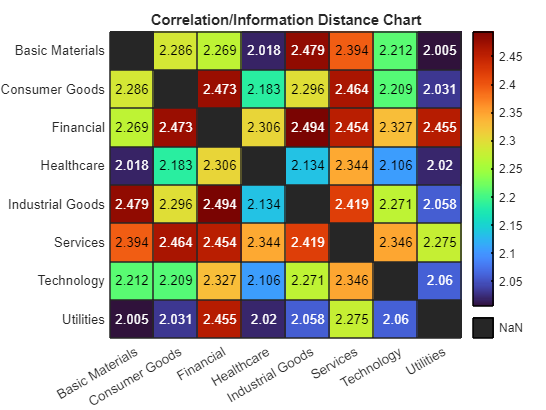

distRatio = sectorDist ./ sectorInfoDist;

figure
heatmap(sectors, sectors, distRatio, "Colormap", turbo)
title("Correlation/Information Distance Chart")

### Repeat the analysis above using the new distance matrix.

Create a heatmap showing the pairwise information distances between the industrial sectors.

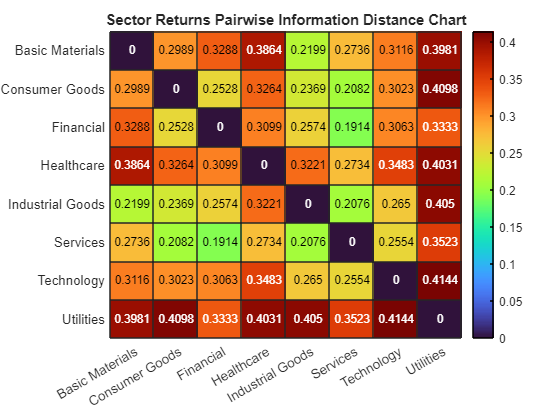

figure
heatmap(sectors, sectors, sectorInfoDist, "Colormap", turbo)
title("Sector Returns Pairwise Information Distance Chart")

### Translate the distance information into graph form.

Remove small numerical asymmetries (the `graph` function requires a perfectly symmetric adjacency matrix).

sectorInfoDist = (sectorInfoDist + sectorInfoDist.')/2;
G = graph(sectorInfoDist, sectors);

Compute the minimal spanning tree.

T = minspantree(G);

Embed the distance matrix in Euclidean space using the Sammon mapping.

coords = mdscale(sectorInfoDist, 3, ...
    "Criterion", "Sammon", ...
    "Replicates", 20);
edgeWeights = T.Edges.Weight;
edgeWidths = 3*edgeWeights/max(edgeWeights);

Visualize the minimum spanning tree computed using the information distance metric

figure
treePlot = plot(T, "XData", coords(:, 1), ...
    "YData", coords(:, 2), ...
    "EdgeLabel", edgeWeights, ...
    "LineWidth", edgeWidths, ...
    "MarkerSize", 5);
title("Sector Returns Minimum Distance Spanning Tree")
axis off

### Compute various centrality metrics derived from the sector tree.

incidence = centrality(T, "degree");
closeness = centrality(T, "closeness", "Cost", edgeWeights);
betweenness = centrality(T, "betweenness", "Cost", edgeWeights);

Visualize these metrics. Begin with the node incidence.

figure
tiledlayout(2, 2)
nexttile([2, 1])

[incSort, sortPos] = sort(incidence);
barh(1:2:numel(incSort), incSort(1:2:end), "FaceColor", "b", "BarWidth", 0.25, "FaceAlpha", 0.5)
hold on
barh(2:2:numel(incSort), incSort(2:2:end), "FaceColor", "r", "BarWidth", 0.25, "FaceAlpha", 0.5)
xticks(0:max(incSort))
nodeNames = T.Nodes.Name(sortPos);
yticks(1:numel(nodeNames))
yticklabels(nodeNames)
grid on
xlabel("Node Incidence")
title("Sector Returns Tree Node Incidence")

Visualize the closeness.

nexttile(2)
[closeSort, sortPos] = sort(closeness, "descend");
stem(closeSort, "LineWidth", 2, "MarkerSize", 8)
xlim([0, numel(closeSort)+1])
xticks(1:numel(closeSort))
nodeNames = T.Nodes.Name;

Truncate the sector names for compactness.

truncNodeNames = cellfun(@(W) W(1:3), nodeNames, "UniformOutput", false);
xticklabels(truncNodeNames(sortPos))
ylabel("Closeness")
title("Sector Returns Tree Node Closeness")
grid on

Visualize the betweenness.

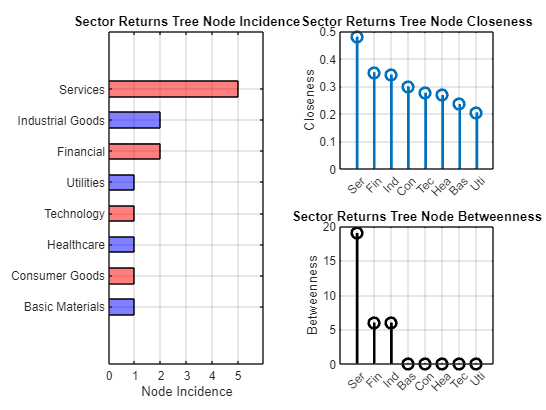

nexttile(4)
[betSort, sortPos] = sort(betweenness, "descend");
stem(betSort, "LineWidth", 2, "MarkerSize", 8, "Color", "k")
xlim([0, numel(betSort)+1])
xticks(1:numel(betSort))
xticklabels(truncNodeNames(sortPos))
ylabel("Betweenness")
title("Sector Returns Tree Node Betweenness")
grid on

This chart shows the graph centrality metrics for the information distance MST.

### Highlight the most central node on the tree by changing its color.

[~, centralNodeIdx] = max(closeness);
nodeColor = treePlot.NodeColor;
nodeColors = repmat(nodeColor, numel(T.Nodes), 1);
nodeColors(centralNodeIdx, :) = [1, 0, 0];
treePlot.NodeColor = nodeColors;

Increase the marker size of the central node.

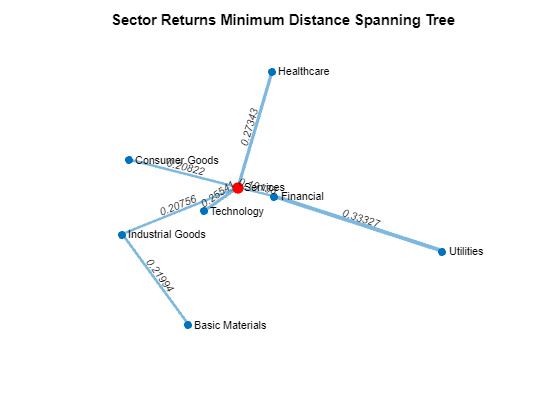

nodeMarkerSize = treePlot.MarkerSize;
nodeMarkerSizes = repmat(nodeMarkerSize, numel(T.Nodes), 1);
nodeMarkerSizes(centralNodeIdx) = 1.5*nodeMarkerSize;
treePlot.MarkerSize = nodeMarkerSizes;

## Modeling risk contagion using hidden Markov models.

When moving from descriptive analysis to modeling, several authors use statistical techniques such as hidden Markov models (see, for example, [6]). Returning to the rolling window analysis, we view the number of highly correlated sector pairs as a basic proxy for the level of risk contagion present in the market.

For simplicity, we’ll assume that three latent, unobserved risk contagion levels, which we name “low”, “medium”, and “high” make up the states of a hidden Markov chain. We take the observed emissions sequence from the Markov chain to be the number of highly correlated sector pairs, which can range from 0 to 28.

The chart below shows the observed data over the time period 2008–2013. We see that there are several periods of high contagion, and that high contagion appears to dissipate at different rates. The lower chart shows the sequence of emission transitions – that is, the differences in the numbers of highly correlated pairs from one window to the next. 

The state transition matrix of the Markov chain is unknown, but we provide an initial estimate as follows.

numStates = 3;
TR = [0.75, 0.125, 0.125; 0.125, 0.75, 0.125; 0.125, 0.125, 0.75];
TR = TR ./ sum(TR, 2);

The rows and columns represent, respectively, the three states "low", "medium" and "high" risk contagion.

The emission probability matrix is also unknown, but we provide an initial estimate as follows. The rows represent the three hidden states "low", "medium" and "high", and the columns represent the emissions.

The elements of this matrix are defined as follows: entry $(i, j)$ is the probability that symbol $j$ is emitted from state $i$.

numLevels = numel(unique(nHighCorrPairs));
x = linspace(0, 5, numLevels);
x = x / sum(x);
EM = [fliplr(x); ones(1, numLevels)/numLevels; x];

Compute the percentage of highly correlated pairs.

percentHighCorr = 100 * nHighCorrPairs / nchoosek(numel(sectors), 2);

Convert to discrete integer emission values. Use a row vector for consistency with [`hmmtrain`](matlab: doc hmmtrain) used below.

emissions = double(categorical(percentHighCorr)).';
emissionDates = dates(windowSize+1:end);

Plot the emissions as a discrete process over time.

figure
tiledlayout(2, 1)
nexttile
yyaxis left
stem(emissionDates, emissions, "filled", ".")
ylabel("Emission number")
yyaxis right
plot(emissionDates, percentHighCorr, "r", "LineWidth", 1.5)
xlabel("Final Date in Window")
ylabel("%")
title("Observed Sequence of Emissions")
grid on
legend("Emission Number", "Highly Correlated Pairs (%)")

We also plot the successive differences over time. This allows us to see the level of transition in the emissions process.

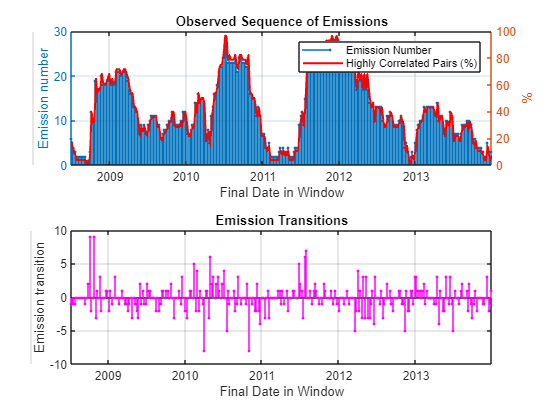

dEmissions = diff(emissions);
nexttile
stem(emissionDates(2:end), dEmissions, "filled", "m.")
xlabel("Final Date in Window")
ylabel("Emission transition")
title("Emission Transitions")
grid on

This chart shows the observed sequence of highly-correlated sector pairs and emission transitions.

### Estimate the underlying transition and emission matrices.

We do this using the sequence of observed emissions from the historical data. Statistics and Machine Learning Toolbox™ provides a framework for constructing hidden Markov models. To estimate the state and emission transition matrices, we use the `hmmtrain` function, providing initial guesses `TR` and `EM` for the unknown matrices.

Estimate the transition and emission matrices from the observed sequence of emissions.

[estTR, estEM] = hmmtrain(emissions, TR, EM);

### Visualise the transition matrix.

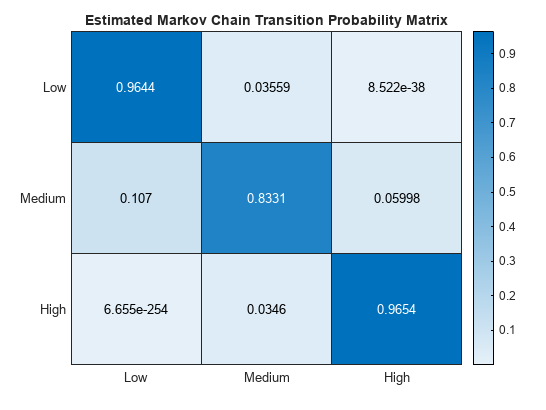

stateNames = ["Low", "Medium", "High"];

figure
heatmap(stateNames, stateNames, estTR)
title("Estimated Markov Chain Transition Probability Matrix")

To check the robustness of the estimated matrices, we could cross-validate on subsets of the emissions vector to make sure that the algorithm converges to the same matrices. The diagram below shows the Markov chain obtained from the data. There are high probabilities of remaining in the same state, and small but non-trivial probabilities of transitioning by one level up or down. There is a negligible chance of transitioning two levels up or down in one step.

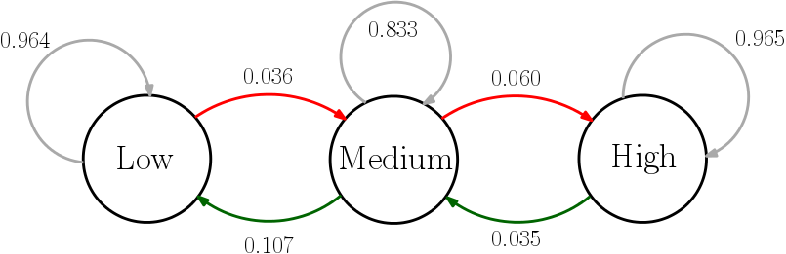

Markov chain transition probabilities computed using `hmmtrain`.

### We now obtain the most likely sequence of states.

The [`hmmviterbi`](matlab: doc hmmviterbi) function retrospectively estimates the most likely sequence of states.

states = hmmviterbi(emissions, estTR, estEM, "Statenames", stateNames).';

We also compute the posterior state probabilities using [`hmmdecode`](matlab: doc hmmdecode).

pstates = hmmdecode(emissions, estTR, estEM).';

Tabulate the results.

hmmResults = table(emissionDates, states, ...
    pstates(:, 1), pstates(:, 2), pstates(:, 3));
hmmResults.Properties.VariableNames = ["Date", "LikelyState", "LowProb", "MedProb", "HighProb"];
hmmResults.LikelyState = categorical(hmmResults.LikelyState, ...
    stateNames, "Ordinal", true);
disp(hmmResults)

       Date        LikelyState      LowProb       MedProb       HighProb  
    ___________    ___________    ___________    __________    ___________

    30-Jun-2008      Low                    1    1.1407e-13              0
    07-Jul-2008      Low                    1    6.9978e-21              0
    14-Jul-2008      Low                    1    2.4511e-49              0
    21-Jul-2008      Low                    1    1.5083e-29              0
    28-Jul-2008      Low                    1    4.8058e-50              0
    04-Aug-2008      Low                    1    4.8058e-50              0
    11-Aug-2008      Low                    1    4.8058e-50              0
    18-Aug-2008      Low                    1    4.8058e-50              0
    25-Aug-2008      Low                    1    4.8058e-50              0
    

The tabulated results provide insight into the market conditions over the historical period. The second column contains the output state from `hmmviterbi`, and columns 3-5 contain the posterior state probabilities from `hmmdecode`. Similarly, we gain insight into the efficacy of this model by comparing the likely states with the observed market data.

### Visualise the HMM results.

Look at the distribution of the estimated likely time-series states over the historical period.

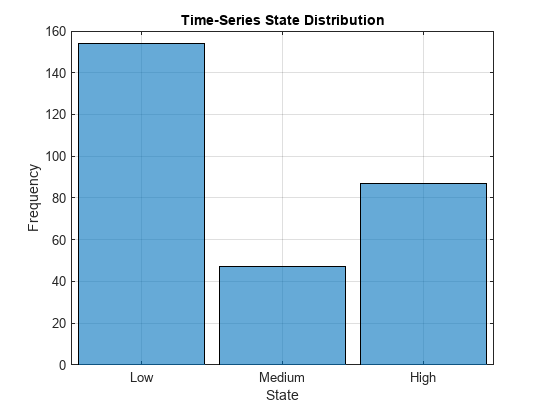

figure
histogram(hmmResults.LikelyState)
xlabel("State")
ylabel("Frequency")
title("Time-Series State Distribution")
grid on

Plot the Markov chain states as a single time series together with the observed market data.

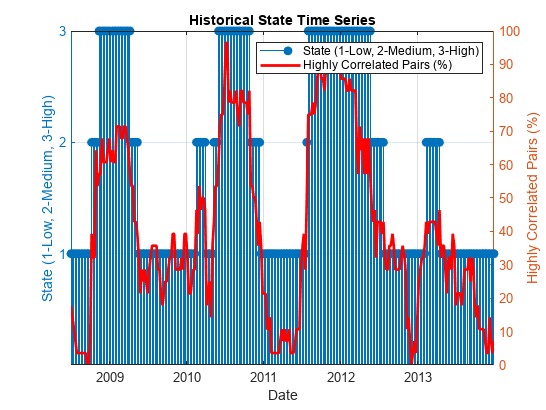

figure
yyaxis left
stem(emissionDates, double(hmmResults.LikelyState), "filled", "o")
ylabel("State (1-Low, 2-Medium, 3-High)")
yticks(1:numStates)
yyaxis right
plot(emissionDates, percentHighCorr, "r", "LineWidth", 2)
xlabel("Date")
ylabel("Highly Correlated Pairs (%)")
title("Historical State Time Series")
grid on
legend("State (1-Low, 2-Medium, 3-High)", "Highly Correlated Pairs (%)")

## Summary and next steps.

Understanding systemic risk requires careful modeling and analysis. In this article we implemented techniques for quantifying proximity between financial variables, including correlation and information distance. We have seen how to visualize proximity information using graph theory. Quantifying and visualizing relationships between variables is important at the exploratory stage of data analysis. Moving to the modeling stage, we created a simple model for risk contagion by fitting a hidden Markov model to the observed data.

To extend the techniques described in this article and include other aspects of systemic risk in our analysis, we could make use of advanced models available in other MATLAB toolboxes, including:

- Time-series and state-space models (in Econometrics Toolbox™)

- Market and credit risk models (in Financial Toolbox™)

- Instrument pricing functionality (in Financial Instruments Toolbox™)

**References**

- Resovsky, Marcel, Denis Horvath, Vladimir Gazda, and Marianna Sinicakova, “Minimum Spanning Tree Application in the Currency Market”, *Currency Market*, 7/2013 [http://www.nbs.sk/_img/Documents/_PUBLIK_NBS_FSR/Biatec/Rok2013/07-2013/05_biatec13-7_resovsky_EN.pdf](http://www.nbs.sk/_img/Documents/_PUBLIK_NBS_FSR/Biatec/Rok2013/07-2013/05_biatec13-7_resovsky_EN.pdf)

- McDoland, Mark, Omer Suleman, Stacy Williams, Sam Howison, and Neil F. Johnson, “Detecting a Currency’s Dominance or Dependence using Foreign Exchange Network Trees”*,* [http://cfr.statslab.cam.ac.uk/events/content/20056/WilliamsPaper.pdf](http://cfr.statslab.cam.ac.uk/events/content/20056/WilliamsPaper.pdf)

- Ouyang, Hong-bing and Xiao-dong Liu, *An Analysis of the Systemic Importance and Systemic Risk Contagion Mechanism of China"s Financial Institutions Based on Network Analysis,* Hong-bing Ouyang, Xiao-dong Liu, CMS, 2015,V23(10): 30-37

- Lori, Giulia, Giulia de Masi, Ovidiu V. Precup, Giampaolo Gabbi, and Guido Caldarelli, “A Network Analysis of the Italian Overnight Money Market”*,* Department of Economics, Discussion Paper Series, No. 05/05, [https://www.city.ac.uk/__data/assets/pdf_file/0017/90260/0505_iori-et-al.pdf](https://www.city.ac.uk/__data/assets/pdf_file/0017/90260/0505_iori-et-al.pdf)

- Kaya, Hakan, “Eccentricity in asset management”*,The Journal of Network Theory in Finance*, Volume 1, Number 1 [http://www.risk.jbs.cam.ac.uk/news/downloads/2015/journalofnetworktheoryinfinance-v1-no1.pdf](http://www.risk.jbs.cam.ac.uk/news/downloads/2015/journalofnetworktheoryinfinance-v1-no1.pdf)

- Staum, Jeremy C., and Ming Liu Staum,”Systemic Risk Components in a Network Model of Contagion”*,* , January 2012. Available at SSRN: [http://ssrn.com/abstract=1726107](http://papers.ssrn.com/sol3/papers.cfm?abstract_id=1726107)

- Bisias, Dimitrios, Mark Flood, Andrew W. Lo, and Stavros Valavanis, “A Survey of Systemic Risk Analytics”*,* Office of Financial Research, Working Paper #0001, January 5th 2012 [https://financialresearch.gov/working-papers/files/OFRwp0001_BisiasFloodLoValavanis_ASurveyOfSystemicRiskAnalytics.pdf](https://financialresearch.gov/working-papers/files/OFRwp0001_BisiasFloodLoValavanis_ASurveyOfSystemicRiskAnalytics.pdf)

**Products Used**

- [MATLAB](http://www.mathworks.com/products/matlab)

- [Parallel Computing Toolbox](http://www.mathworks.com/products/parallel-computing)

- [Statistics and Machine Learning Toolbox](http://www.mathworks.com/products/statistics)

**Learn More**

- [Risk Management: Overview and Resources](http://www.mathworks.com/solutions/financial-services/risk-management.html)

- [Systemic Risk: Overview and Resources](http://www.mathworks.com/discovery/systemic-risk.html)

- [Exploring Risk Contagion (code download)](https://uk.mathworks.com/matlabcentral/fileexchange/57046-exploring-risk-contagion-using-graph-theory-and-markov-chains-live-editor-version)